# Transitions between periodic orbits in the forced Shaw-Pierre system

We consider the following mechanical system, describing a system of coupled nonlinear oscillators.


$$\left(\begin{array}{c}
\dot{q_{1}}\\
\dot{p}_{1}\\
\dot{q_{2}}\\
\dot{p_{2}}
\end{array}\right)=\left(\begin{array}{cccc}
0 & 1 & 0 & 0\\
-2\frac{k}{m} & -\frac{c}{m} & \frac{k}{m} & \frac{c}{m}\\
0 & 0 & 0 & 1\\
\frac{k}{m} & \frac{c}{m} & -2\frac{k}{m} & -2\frac{c}{m}
\end{array}\right)\left(\begin{array}{c}
q_{1}\\
p_{1}\\
q_{2}\\
p_{2}
\end{array}\right)+\left(\begin{array}{c}
0\\
A\cos\Omega t-\frac{\gamma}{m}q_{1}^{3}\\
0\\
0
\end{array}\right).
$$


For a forcing amplitude of A = 0.11 and $\Omega$=1.068 three periodic orbits coexist: a high amplitude stable periodic orbit, a saddle-type periodic orbit and a low amplitude stable periodic orbit. They have been precomputed along with their Floquet multipliers and have been saved in data.mat.

load('data.mat');

c1 = 0.03; 
c2 = 0.03;
k = 1;
gamma = 0.5;

period = 2*pi/ frequency;
odefun = @(t, x) shawpierre(t, x, c1, c2, k, gamma, amplitude, frequency);

opts = odeset('reltol', 1e-8, 'abstol', 1e-9);

[~, orbitSaddle] = ode45(odefun, linspace(0, period, 1000), SaddleIC, opts);

[~, orbitLower] = ode45(odefun, linspace(0, period, 1000), LowerIC, opts);
[~, orbitUpper] = ode45(odefun, linspace(0, period, 1000), UpperIC, opts);

Plot the three coexisting orbits

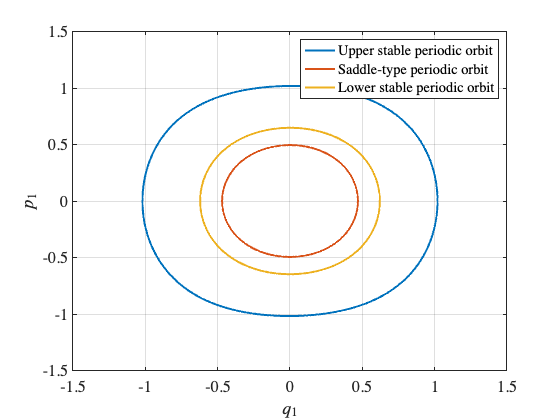

customFigure('latex', true);
plot(orbitUpper(:,1), orbitUpper(:,2), '-', 'linewidth', 2, 'DisplayName', 'Upper stable periodic orbit');
plot(orbitLower(:,1), orbitLower(:,2), '-', 'linewidth', 2, 'DisplayName', 'Saddle-type periodic orbit');
plot(orbitSaddle(:,1), orbitSaddle(:,2), '-', 'linewidth', 2, 'DisplayName', 'Lower stable periodic orbit');
xlabel('$q_1$')
ylabel('$p_1$')

legend()

In the following analysis, we introduce the Poincare-map, which is the time-T map of the dynamics, where T is the common period of all three periodic orbits and is given by $T = \frac{2\pi}{\Omega}$. The three periodic orbits are thus fixed points of the Poincare-map. The eigenvalues of the linearized Poincare-map are referred to as Floquet-multipliers. 

The saddle-type orbit has a single (real) unstable Floquet-multiplier and its slowest stable multiplier is also real. This suggests that the slowest spectral submanifold is tangent to the span of these two leading eigenvectors and hence is two dimensional. 

To find this spectral submanifold we initialize four training trajectories in the vicinity of the saddle-type orbit: 


$$x_{0}^{(1,2,3,4)}=x_{0}\pm\delta\mathbf{e}_{1}\pm\delta\mathbf{e}_{2},$$


 where  $x_0$ is the saddle-type fixed point of the Poincare-map, $e_1$is its unstable eigenvector,  $e_2$ is its weakest stable eigenvector, and $\delta = 0.01.$

e1 = SaddleEigenvectors(:,4);
e2 = SaddleEigenvectors(:,3);
perturbMagnitude = 1e-2;

ic1 = SaddleIC' + perturbMagnitude * e1 + perturbMagnitude * e2;
ic2 = SaddleIC' + perturbMagnitude * e1 - perturbMagnitude * e2;
ic3 = SaddleIC' - perturbMagnitude * e1 + perturbMagnitude * e2;
ic4 = SaddleIC' - perturbMagnitude * e1 - perturbMagnitude * e2;



[t1, train1] = poincareMap(ic1, odefun, frequency, 200, opts);
[t2, train2] = poincareMap(ic2, odefun, frequency, 200, opts);
[t3, train3] = poincareMap(ic3, odefun, frequency, 200, opts);
[t4, train4] = poincareMap(ic4, odefun, frequency, 200, opts);

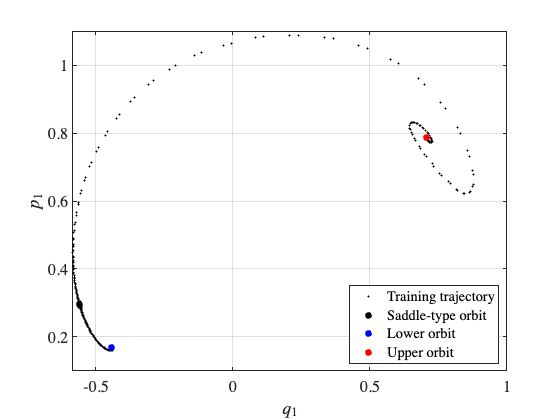

customFigure('latex', true);
plot(train1(:,1), train1(:,2), '.', 'Color', 'black', 'DisplayName','Training trajectory' );
plot(train2(:,1), train2(:,2), '.', 'Color', 'black', 'HandleVisibility','off');

plot(train3(:,1), train3(:,2), '.','Color', 'black',  'HandleVisibility','off');
plot(train4(:,1), train4(:,2), '.', 'Color', 'black', 'HandleVisibility','off');

plot(SaddleIC(1), SaddleIC(2), 'k.', 'markersize', 20, 'DisplayName','Saddle-type orbit')
plot(LowerIC(1), LowerIC(2), 'b.', 'markersize', 20, 'DisplayName','Lower orbit')
plot(UpperIC(1), UpperIC(2), 'r.', 'markersize', 20, 'DisplayName','Upper orbit')

xlabel('$q_1$')
ylabel('$p_1$')

legend('location', 'SE')

We first set up the cell arrays for SSMLearn. We use the first two degrees of freedom as the parametrizing variable, i. e. $q_1, p_1$

xData = {};
aData = {};
aData{1,1} = t1';
aData{1,2} = train1';

aData{2,1} = t2';
aData{2,2} = train2';
aData{3,1} = t3';
aData{3,2} = train3';

aData{4,1} = t4';
aData{4,2} = train4';


xData{1,1} = t1';
xData{1,2} = train1(:,1:2)';

xData{2,1} = t2';
xData{2,2} = train2(:,1:2)';
xData{3,1} = t3';
xData{3,2} = train3(:,1:2)';

xData{4,1} = t4';
xData{4,2} = train4(:,1:2)';

nTrain = 4;
indTrain = [1,2,3,4];

We now generate 20 test trajectories initialized from the neighborhood of the saddle-type orbit and add them to the cell arrays.

perturbMagnitudeTest = 1e-2;
nTest = 20;
rng(5); % set seed

for iTraj = nTrain+1:nTrain+nTest
    randomIC = SaddleIC' + (rand(4,1)-0.5)*perturbMagnitudeTest;
    [ttest,ttraj] = poincareMap(randomIC, odefun, frequency, 200, opts);
    xData{iTraj,1} = ttest';
    xData{iTraj,2} = ttraj(:, 1:2)';
    
    aData{iTraj,1} = ttest';
    aData{iTraj,2} = ttraj';
end

indTest = nTrain+1:nTrain+nTest;

## Preprocessing the data

We shift the coordinates such that the origin is at the saddle point. We also cut the first part of the test trajectories.

nTrajs = nTrain + nTest;
startTest = 16;
etaData = {};
yData = {};
for iTraj=1:nTrajs
    yData{iTraj, 1} = aData{iTraj,1};
    yData{iTraj, 2} = aData{iTraj,2} - SaddleIC';

    etaData{iTraj, 1} = xData{iTraj,1};

    etaData{iTraj, 2} = xData{iTraj,2} - SaddleIC(1:2)';


end

for iTraj=indTest
    yData{iTraj, 1} = yData{iTraj,1}(startTest:end);
    yData{iTraj, 2} = yData{iTraj,2}(:, startTest:end);

    etaData{iTraj, 1} = etaData{iTraj, 1}(startTest:end);
    etaData{iTraj, 2} = etaData{iTraj,2}(:, startTest:end);


end

## Fit the reduced dynamics 

Afterwards we display the predictions on training and test trajectories

polynomialOrder = 5;
l_vals = logspace(-16,-1,101); n_folds = 5;
RDInfo = IMDynamicsMap(etaData(indTrain,:),'R_PolyOrd', polynomialOrder,...
    'l_vals',0); 

Estimation of the reduced dynamics...  Done. 


R = RDInfo.reducedDynamics.map; 


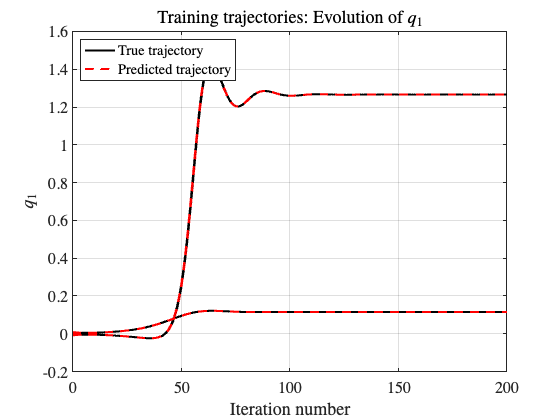

etaRec = iterateMaps(R, etaData);

customFigure('latex', true);
title('Training trajectories: Evolution of $q_1$')
for iTraj = indTrain
    
    if iTraj == indTrain(1)
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(1,:), 'k-', 'linewidth', 2, 'Displayname', 'True trajectory');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(1,:), 'r--', 'linewidth', 2, 'Displayname', 'Predicted trajectory');
       

    else
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(1,:), 'k-', 'linewidth', 2, 'HandleVisibility', 'off');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(1,:), 'r--', 'linewidth', 2, 'HandleVisibility', 'off');
      
    end

end
ylabel('$q_1$');
xlabel('Iteration number');
legend('location', 'NW');

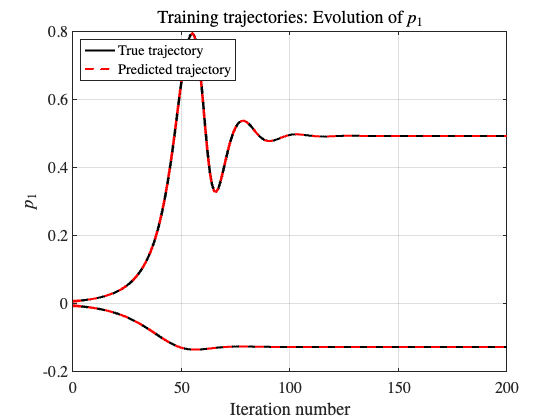


customFigure('latex', true);
title('Training trajectories: Evolution of $p_1$')
for iTraj = indTrain
    
    if iTraj == indTrain(1)
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(2,:), 'k-', 'linewidth', 2, 'Displayname', 'True trajectory');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(2,:), 'r--', 'linewidth', 2, 'Displayname', 'Predicted trajectory');
       

    else
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(2,:), 'k-', 'linewidth', 2, 'HandleVisibility', 'off');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(2,:), 'r--', 'linewidth', 2, 'HandleVisibility', 'off');
      
    end

end
ylabel('$p_1$');
xlabel('Iteration number');
legend('location', 'NW');

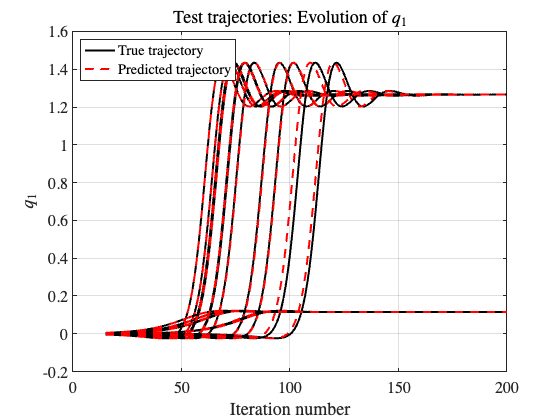

customFigure('latex', true);
title('Test trajectories: Evolution of $q_1$')
for iTraj = indTest
    
    if iTraj == indTest(1)
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(1,:), 'k-', 'linewidth', 2, 'Displayname', 'True trajectory');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(1,:), 'r--', 'linewidth', 2, 'Displayname', 'Predicted trajectory');
       

    else
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(1,:), 'k-', 'linewidth', 2, 'HandleVisibility', 'off');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(1,:), 'r--', 'linewidth', 2, 'HandleVisibility', 'off');
      
    end

end
ylabel('$q_1$');
xlabel('Iteration number');
legend('location', 'NW');

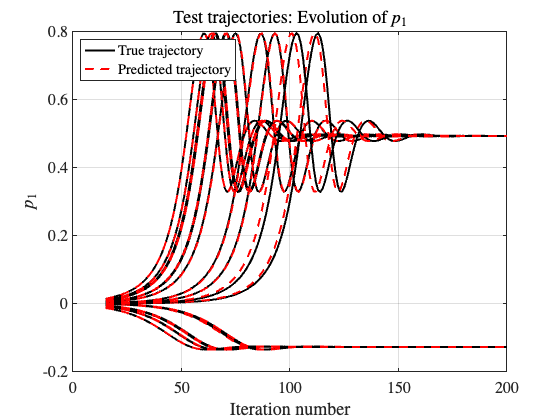

customFigure('latex', true);
title('Test trajectories: Evolution of $p_1$')
for iTraj = indTest
    
    if iTraj == indTest(1)
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(2,:), 'k-', 'linewidth', 2, 'Displayname', 'True trajectory');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(2,:), 'r--', 'linewidth', 2, 'Displayname', 'Predicted trajectory');
       

    else
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaData{iTraj,2}(2,:), 'k-', 'linewidth', 2, 'HandleVisibility', 'off');
       plot(etaData{iTraj,1}/RDInfo.mapTimeStep, etaRec{iTraj,2}(2,:), 'r--', 'linewidth', 2, 'HandleVisibility', 'off');
      
    end

end
ylabel('$p_1$');
xlabel('Iteration number');
legend('location', 'NW');

## Fitting the parametrization of the manifold

We also visualize the 2D manifold along with the training and test trajectories. 

SSMDim = 2;
IMInfo = IMGeometry(yData(indTrain,:),SSMDim, polynomialOrder,'reducedCoordinates',etaData(indTrain,:));

parametrization = IMInfo.parametrization.map;

To visualize the SSM, we set up a grid in the $q_1, p_1$ plane.

q1min = -0.6;
q1max = 1;
p1min = 0.0;
p1max = 1.3;

qq = linspace(q1min, q1max, 50)-SaddleIC(1);
pp = linspace(p1min, p1max, 50) - SaddleIC(2);
[Q, P] = meshgrid(qq, pp);
Grid = [Q(:), P(:)]';
%Grid = Grid - SaddleIC(1:2)'; % have to shift coordinates of the grid (parametrization assumes that the saddle is at the origin)


Z = parametrization(Grid);

Z3 = Z(3, :); % plot only q_2 
Z3 = reshape(Z3, size(Q)); % reshape for surf()

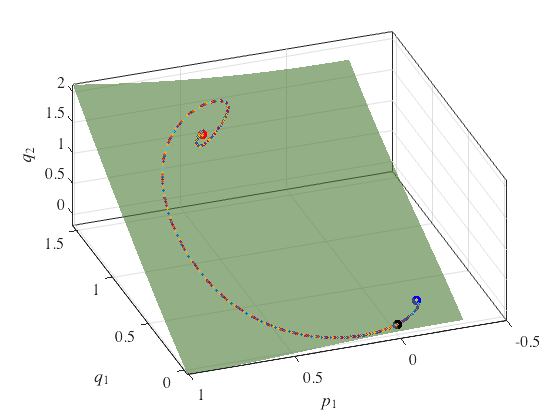

customFigure('latex', true);
surf(Q, P, Z3, 'FaceColor','#4B7935', 'edgecolor','none','FaceAlpha', 0.6, 'Displayname', 'SSM')
for iTraj = indTest
    if iTraj == indTest(1)
    plot3(yData{iTraj,2}(1,:), yData{iTraj,2}(2,:), yData{iTraj,2}(3,:), '.', 'markersize', 6.5, 'HandleVisibility', 'off');

    else
    plot3(yData{iTraj,2}(1,:), yData{iTraj,2}(2,:), yData{iTraj,2}(3,:), '.', 'markersize', 7, 'HandleVisibility', 'off');
   
    end

end

plot3(yData{1,2}(1,end), yData{1,2}(2,end), yData{1,2}(3,end), 'r.', 'markersize', 30, 'Displayname', 'Upper orbit');
plot3(yData{3,2}(1,end), yData{3,2}(2,end), yData{3,2}(3,end), 'b.', 'markersize', 30, 'Displayname', 'Lower orbit');
plot3(0,0,0, 'k.', 'markersize', 30, 'Displayname', 'Saddle');


xlabel('$q_1$');
ylabel('$p_1$');
zlabel('$q_2$');

view(3)